clear all

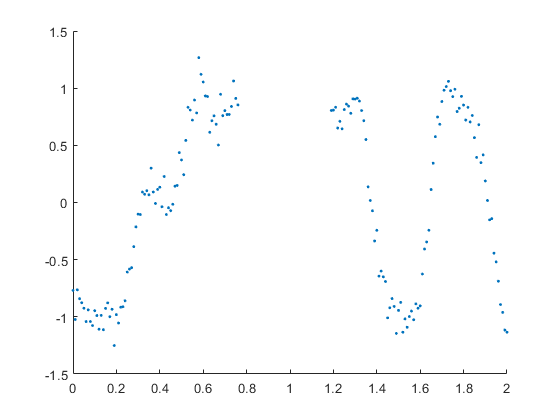

close all
rng(2)
xmax=2;

input = ([0:0.01:xmax])';
noise= 0.1*(randn(size(input)));

difforder = 2;
n = 3;
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input))+noise;
real = sin(exp(input)+sin(10*input).^2+3*cos(3*input));

bs = bspline([0:n+1]);
M = flipud(bs.coefs)';

knotintervals = 35;
knotdist = xmax/knotintervals;


fitindexes = [(1:floor(length(input)/2.6)) (floor(length(input)*3/5):length(input))];
inputfit = input(fitindexes);
outputfit = output(fitindexes);
realfit = real(fitindexes);




scatter(inputfit,outputfit, 5, 'filled')

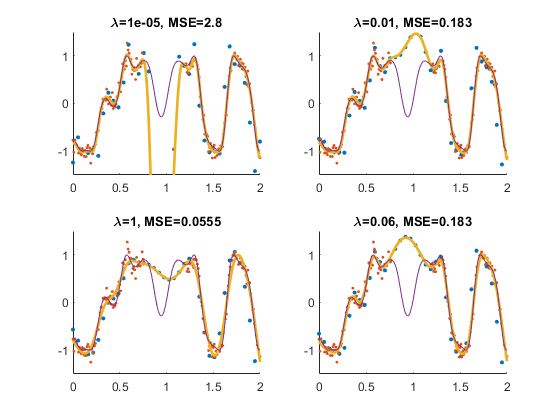

gamm = 0.0571

peNN = [0.00001 0.01 1 1e2 1e3];
ii=0;

% -----------------curve fitting--------------------------

figure;

indexes = floor(input/knotdist)+1;
indexes(end)= knotintervals;

u = (input/knotdist)-indexes+1;
bn = u.^[n:-1:0]*M;

Btot = zeros(length(input),knotintervals+n);
for i=1:length(input)
   Btot(i,indexes(i):indexes(i)+n) = bn(i,:);
end

B=Btot(fitindexes,:);

for itre = 1:1:4
    
    gamm= peNN(itre);
    ii = ii+ 1;


% if ii==1
% P=pinv(B)*output;
% P = B\output;
% spline = B*P(1:end,1);

% else
% P = ridge(output,B,k,0);
% spline = B*P(2:end);
% 
% P = lasso(B,output,'Lambda', k/500);
% spline = B*P(1:end,1);

Y = diff(eye(size(B,2)),1);
PEN1 = Y'*Y;

Y = diff(eye(size(B,2)),2);
PEN2 = Y'*Y;

Y = diff(eye(size(B,2)),3);
PEN3 = Y'*Y;

if ii==4
gamm= length(P)^2/length(inputfit)^2
end

% pen2 = 1/length(inputfit)^2
% +pen2*eye(knotintervals+n)

P = (B'*B+ 0.01*gamm*PEN1 + 0.1*gamm*PEN2 + gamm*PEN3 )\(B'*outputfit);   

% spline = B*P;
% err = immse(spline,realfit);

spline = Btot*P;
err = immse(spline,real);


subplot(2,2,ii)
hold on
axis([0 xmax -1.5 1.5])
% plot(linspace(0,1,length(P)),P)

scatter(linspace(0,xmax,length(P)),P, 10, 'filled')

% plot(input,output)
scatter(inputfit,outputfit, 5, 'filled')
plot(input,spline, 'LineWidth',2)

plot(input,real)

title(['\lambda=', num2str(gamm,1), ', MSE=', num2str(err,3)])
hold off

end

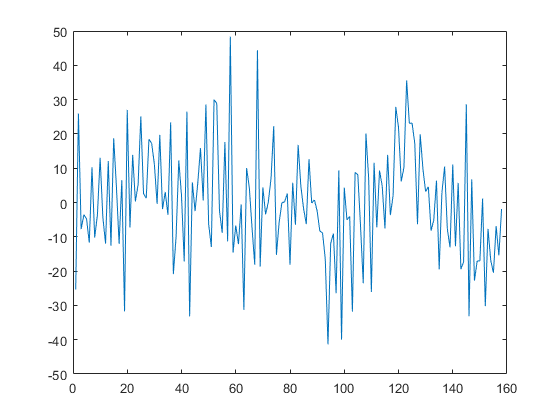


figure;
errorzy = [diff(outputfit,1)]./diff(inputfit);
errorzP = [diff(P,1)]./knotdist;
plot(errorzy)

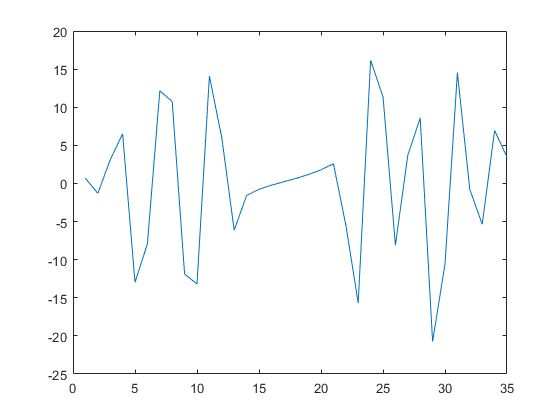

plot(diff(errorzP,2))

norm(errorzy)/length(inputfit)

ans = 1.2857

norm(diff(errorzP,1))/length(P)

ans = 1.0813

% figure;
% hold on
% axis([0 xmax -1.5 1.5])
% % plot(input,output)
% % plot(input,real)
% scatter(input,output, 30, 'filled')
% plot(input,real,'color', 'g', 'LineWidth',2)
% scatter(0:0.1:1,outputint, 100, 'LineWidth',2,'MarkerEdgeColor', 'red')
% hold off


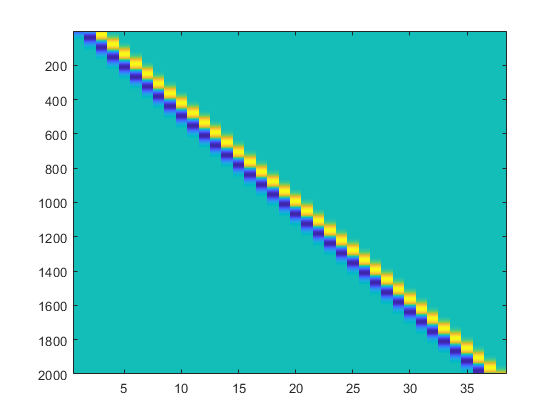

figure;

% ---------gradient 2
bs = bspline([0:n+1]);
M = flipud(bs.coefs)';

ddx=0.001;
inputgrad = (0:ddx:xmax-ddx)';
indexes = floor(inputgrad/knotdist)+1;
% indexes(end)= knotintervals;

u = (inputgrad/knotdist)-indexes+1;

bn0 =  (1/knotdist)*[u.^[n-1:-1:0].*(n:-1:1) zeros(length(inputgrad),1)];

bngrad=bn0*M;
B = zeros(length(inputgrad),knotintervals+n);
for i=1:length(inputgrad)
   B(i,indexes(i):indexes(i)+n) = bngrad(i,:);
end

imagesc(B)


gradient = B*P;
% plot(P)

integral=cumsum(gradient)

integral = 	1.0e+03 *

   -0.0020
   -0.0040
   -0.0060
   -0.0080
   -0.0100
   -0.0120
   -0.0140
   -0.0160
   -0.0181
   -0.0201


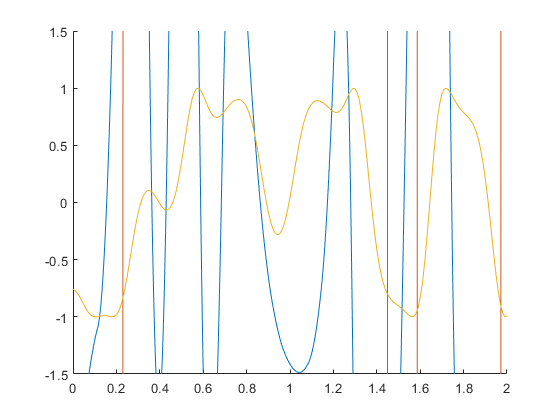

figure;
hold on
axis([0 xmax -1.5 1.5])
plot(inputgrad,gradient)
plot(inputgrad,integral+real(1))
plot(input,real)
% plot(input,spline)
hold off

% 
% % ---------gradient 1
% bs = bspline([0:n]);
% M = flipud(bs.coefs)';
% 
% ddx = 0.001
% inputgrad = (0:ddx:xmax-ddx)';
% indexes = floor(inputgrad/knotdist)+1;
% indexes(end)= knotintervals
% 
% u = (inputgrad/knotdist)-indexes+1;
% 
% bn0 = u.^[n-1:-1:0];
% bn1 = (u-1).^[n-1:-1:0];
% 
% bngrad=(bn0-bn1)*M
% B = zeros(length(inputgrad),knotintervals+n);
% for i=1:length(inputgrad)
%    B(i,indexes(i):indexes(i)+n-1) = bngrad(i,:);
% end
% 
% gradient = B*P;
% % plot(P)
% 
% gradient=ddx*cumsum(gradient)
% figure;
% hold on
% % axis([0 length(output) -1.5 1.5])
% % plot(output)
% plot(inputgrad-0.05,gradient)
% plot(input,real)
% hold off
% 
% % err = immse(gradient,real)


% bb= input.^[34:-1:0]
% 
% P2 = ridge(output,bb,0.00000001,0)
% 
% % P2 = lasso(bb,output)
% % P2=pinv(bb)*output
% plot(P2)
% 
% spline = bb*P2+real(1);
% 
% % spline = []
% % for j = 1:(length(P)-n)
% %    spline = [spline(1:end) ;bn*P(j:j+n)]; 
% % end
% 
% figure;
% hold on
% axis([0 length(output) -1.5 1.5])
% % plot(output)
% plot(spline)
% plot(real)
% hold off
% err = immse(spline,real)



% clear all
% -----------------interpolation--------------------------
% fr=8
ii=0

ii = 0

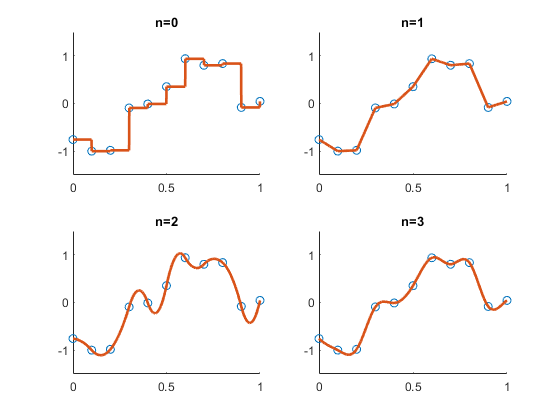

P =    -0.7568
   -0.9995
   -0.9824
   -0.0929
   -0.0101
    0.3533
    0.9386
    0.8021
    0.8372
   -0.0827


ans = 0.9995

P =    -0.7568
   -0.9995
   -0.9824
   -0.0929
   -0.0101
    0.3533
    0.9386
    0.8021
    0.8372
   -0.0827


ans = 0.9995

P =    -0.7355
   -0.7781
   -1.2208
   -0.7439
    0.5582
   -0.5783
    1.2849
    0.5923
    1.0119
    0.6625


ans = 1.2849

P =    -0.1839
   -0.8478
   -0.9657
   -1.2861
    0.2161
   -0.1356
    0.2660
    1.1916
    0.5995
    1.2234


ans = 1.2861

figure;

for n=0:3
    
ii = ii+1;
% n = 0

xmax=1;
dx=0.1;
input = (0:dx:xmax)';
outputint = sin(exp(input)+sin(10*input).^2+3*cos(3*input));
real = sin(exp(input)+sin(10*input).^2+3*cos(3*input));

knotintervals = length(input);
knotdist = dx ;%xmax/knotintervals;

bs = bspline([0:n+1]);
M = flipud(bs.coefs)';
% figure;
% hold on
% axis([0 xmax -1.5 1.5])
% % scatter(1:11,output)
% scatter(input,real)
% hold off

indexes = floor((input+eps)/knotdist)+1;
indexes(end)= knotintervals;
% plot(indexes);

u = ((input+eps)/knotdist)-indexes+1;
bn = u.^[n:-1:0]*M;

Bint = zeros(length(input),knotintervals+n);
for i=1:length(input)
   Bint(i,indexes(i):indexes(i)+n) = bn(i,:);
end

% imagesc(Bint)

% Bint = Bint(:,2:size(Bint,1)+1)

% Bint = [Bint;zeros(n, size(Bint,2))]
% P=pinv(Bint)*output;

% P=Bint\output

P = lsqminnorm(Bint,outputint)

% ----- plotting
input2 = (0:dx/100:xmax)';
indexes2 = floor(input2/knotdist)+1;
u = (input2/knotdist)-indexes2+1;
bn = u.^[n:-1:0]*M;

B = zeros(length(u),knotintervals+n);
for i=1:length(u)
   B(i,indexes2(i):indexes2(i)+n) = bn(i,:);
end


% B = B(:,2:size(Bint,1)+1)

% [U,S,V] = svd(B)

% plot(diag(S))

spline = B*P;

max(abs(P))

subplot(2,2,ii)
hold on
scatter(input,real)
plot(input2,spline, 'LineWidth',2)
axis([0 xmax -1.5 1.5])
title(['n=', num2str(n)])
hold off
end

n = 5

n = 5

knotintervals = 4;
xmax=1

xmax = 1

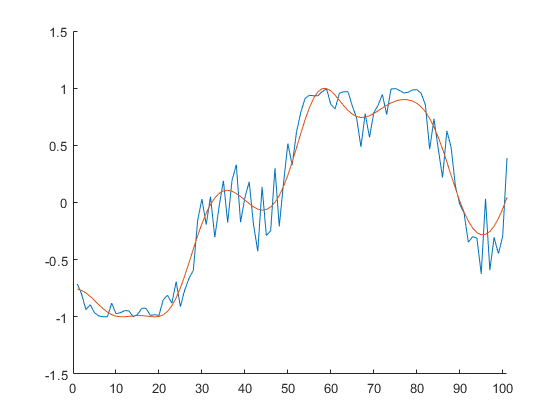


knotdist = xmax/knotintervals;
input = (0:0.01:xmax)';
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.8*(rand(size(input))-0.5));
real = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0*rand(size(input)));

bs = bspline([0:n+1]);
M = flipud(bs.coefs)';
figure;
hold on
axis([0 length(input) -1.5 1.5])
plot(output)
plot(real)
hold off


indexes = floor(input/knotdist)+1;
indexes(end)= knotintervals

indexes =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


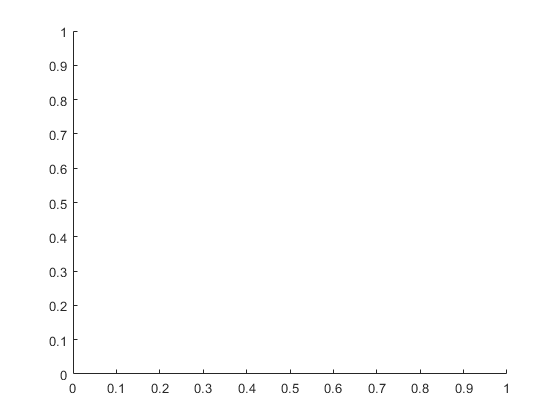


u = (input/knotdist)-indexes+1;
bn = u.^[n:-1:0]*M;

B = zeros(length(input),knotintervals+n);
for i=1:length(input)
   B(i,indexes(i):indexes(i)+n) = bn(i,:);
end


figure;
hold on


Pp{1}=B*[1 0 0 0 0 0 ]';

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Pp{2}=B*[0 1 0 0 0 0 ]';
Pp{3}=B*[0 0 1 0 0 0 ]';
Pp{4}=B*[0 0 0 1 0 0 ]';
Pp{5}=B*[0 0 0 0 1 0 ]';
Pp{6}=B*[0 0 0 0 0 1 ]';

for i=1:6
plot(input,Pp{i},'LineWidth',1)

% plot(plotter-2,Pp{i},'LineWidth',1,'color',[0 1-i/7 i/7])
end
hold off
axis([0 1 0 1])
% legend('B_{i,2}(x)','B_{1,2}(x)','B_{2,2}(x)')
